# **Jordan Holbroook**

# **Macroeconometrics (Spring 2022)**

## **Homework 3: Cointegration**

## Question 1. 

Download (or re-use) 3 series from the BEA and test if your variables are co-integrated

### Load the Data and verify that the series are Unit Root Processes

clc
clear
clf

load Data_USEconModel


rcpi = price2ret(DataTable.CPIAUCSL);
%unrate = DataTable.UNRATE(2:end);
%fedfunds = DataTable.FEDFUNDS(2:end);

pi = DataTable.CPIAUCSL(31:end);
u = DataTable.UNRATE(31:end);
r = DataTable.FEDFUNDS(31:end);

T = length(pi);

test = adftest(pi,'model','TS','lags',0:2)

test = 1×3 logical array
   1   0   0


test1 = adftest(u,'model','TS','lags',0:1)

test1 = 1×2 logical array
   0   0


test2 = adftest(r,'model','TS','lags',0:2)

test2 = 1×3 logical array
   0   0   0


## Engle-Granger Test of Unemployment and Fed Funds for Cointegration


% First Stage
    coeff = [0 1];
    X = [ones(T,1) r];
    Y = u;    
    b_ols = (X'*X)\X'*Y;
        
    e_ols  = Y - X*b_ols;
    s2_ols = e_ols'*e_ols/(T-size(X,2));
    
    ols_mat(1,1:2) = b_ols';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    v_ols  = s2_ols./(X'*X);
    
 % Second Stage
 
    Y1 = e_ols(1:T-1);
    X1 = [ones(T-1,1) e_ols(2:T)];
    
    b_ols1 = (X1'*X1)\X1'*Y1;
        
    e_ols1  = Y1 - X1*b_ols1;
    s2_ols1 = e_ols1'*e_ols1/(T-size(X1,2));
    
    ols_mat1(1,1:2) = b_ols1';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    v_ols1  = s2_ols1./(X1'*X1);
    
 % Hypothesis Test that Second Stage Coefficient is different than 1
 
    t_stats = (ols_mat1-coeff)./(sqrt(diag(v_ols1))');
    t_stats_beta1 = t_stats(2);

    

**Print Results**

% Critical Value for Dickey-Fuller t-distribution at 5% level
critical_value = -2.88

critical_value = -2.8800

if abs(t_stats(2)) > abs(critical_value)
    fprintf("The Engle-Granger Test Provides Evidence against the Null Hypothesis of No Cointegration \n ..." + ...
        " Thus we have evidence that Inflation and Fed Funds are Cointegrated")
else
    fprintf("The Engle-Granger Test Provides Evidence in favor of the Null Hypothesis of No Cointegration")
end

The Engle-Granger Test Provides Evidence against the Null Hypothesis of No Cointegration 
 ... Thus we have evidence that Inflation and Fed Funds are Cointegrated

## Engle-Granger Test of **Fed Funds and Inflation for Cointegration**

% First Stage
    coeff = [0 1];
    X = [ones(T,1) pi];
    Y = r;    
    b_ols = (X'*X)\X'*Y;
        
    e_ols  = Y - X*b_ols;
    s2_ols = e_ols'*e_ols/(T-size(X,2));
    
    ols_mat(1,1:2) = b_ols';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    v_ols  = s2_ols./(X'*X);
    
 % Second Stage
 
    Y1 = e_ols(1:T-1);
    X1 = [ones(T-1,1) e_ols(2:T)];
    
    b_ols1 = (X1'*X1)\X1'*Y1;
        
    e_ols1  = Y1 - X1*b_ols1;
    s2_ols1 = e_ols1'*e_ols1/(T-size(X1,2));
    
    ols_mat1(1,1:2) = b_ols1';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    v_ols1  = s2_ols1./(X1'*X1);
    
 % Hypothesis Test that Second Stage Coefficient is different than 1
 
    t_stats = (ols_mat1-coeff)./(sqrt(diag(v_ols1))');
    t_stats_beta1 = t_stats(2);

    
    

**Print Results**

% Critical Value for Dickey-Fuller t-distribution at 5% level
critical_value = -2.88

critical_value = -2.8800



if abs(t_stats(2)) > abs(critical_value)
    fprintf("The Engle-Granger Test Provides Evidence against the Null Hypothesis of No Cointegration \n ..." + ...
        " Thus we have evidence that Inflation and Fed Funds are Cointegrated")
else
    fprintf("The Engle-Granger Test Provides Evidence in favor of the Null Hypothesis of No Cointegration")
end

The Engle-Granger Test Provides Evidence in favor of the Null Hypothesis of No Cointegration

### Engle-Granger Test of **Inflation and Unemployment for Cointegration**

% First Stage
    coeff = [0 1];
    X = [ones(T,1) u];
    Y = pi;    
    b_ols = (X'*X)\X'*Y;
        
    e_ols  = Y - X*b_ols;
    s2_ols = e_ols'*e_ols/(T-size(X,2));
    
    ols_mat(1,1:2) = b_ols';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    v_ols  = s2_ols./(X'*X);
    
 % Second Stage
 
    Y1 = e_ols(1:T-1);
    X1 = [ones(T-1,1) e_ols(2:T)];
    
    b_ols1 = (X1'*X1)\X1'*Y1;
        
    e_ols1  = Y1 - X1*b_ols1;
    s2_ols1 = e_ols1'*e_ols1/(T-size(X1,2));
    
    ols_mat1(1,1:2) = b_ols1';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    v_ols1  = s2_ols1./(X1'*X1);
    
 % Hypothesis Test that Second Stage Coefficient is different than 1
 
    t_stats = (ols_mat1-coeff)./(sqrt(diag(v_ols1))');
    t_stats_beta1 = t_stats(2);

    
    

**Print Results**

% Critical Value for Dickey-Fuller t-distribution at 5% level
critical_value = -2.88

critical_value = -2.8800



if abs(t_stats(2)) > abs(critical_value)
    fprintf("The Engle-Granger Test Provides Evidence against the Null Hypothesis of No Cointegration \n ..." + ...
        " Thus we have evidence that Unemployment and Inflation are Cointegrated")
else
    fprintf("The Engle-Granger Test Provides Evidence in favor of the Null Hypothesis of No Cointegration")
end

The Engle-Granger Test Provides Evidence against the Null Hypothesis of No Cointegration 
 ... Thus we have evidence that Unemployment and Inflation are Cointegrated

## Question 2. i)

For any non-zero value of $\alpha$,  $$y_t$$  is a unit root process. Try and test for unit roots in $$y_t$$ for $\alpha$ = 0.1 and 1.0, respectively. Test for a unit root. Does the test correctly identify non-stationarity in each case (do a number of iterations and show the distribution)? (For this construction,$\alpha$ would be “size” of the unit root.

## Set the parameters.

clc
clear
clf

global y T

T = 300;                             % Number of time periods.
mu = 0;                           % Mu.
alpha =0.1;                       % Alpha.
sigma = 1;                         % Standard deviation.

sim = 50;                             % Number of simulations.
                                  
ols_mat = zeros(sim,3);                                      % OLS matrix.
t_stat_vect = zeros(sim,1);                                 % Vector to capture empirical t-stats


## **Unit Root Test**


for s = 1:sim
    
    % Draw error terms.
    
    e = normrnd(0,2,T,1); %innovations for y
    
    u = normrnd(0,3,T,1); %innovations for x
    
    y = zeros(T,1);
    x = zeros(T,1);
    for i=2:T
        x(i,:) = x(i-1) + u(i,:);
        y(i,:) = alpha*x(i,:) + e(i,:);
    end
    
     %differnece and prepare for OLS
    
    Ldeltay = y(3:T,:) - y(2:T-1,:);
    Ly = y(2:T-1,:);
    deltay = y(2:T-1,:)- y(1:T-2,:);
    t = [3:T]';
    intercept = ones(T-2,1);

    
    % OLS.
    X = [intercept(:,1) t(:,1) Ly deltay];
    Y = Ldeltay;
      
    b_ols = (X'*X)\X'*Y;
        
    u_ols  = Y - X*b_ols;
    s2_ols = u_ols'*u_ols/((T-2)-size(X,2));
    
    ols2_mat(s,1:length(b_ols)) = b_ols';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    %v2_ols  = s2_ols./(X'*X);
    v_ols  = s2_ols*inv(X'*X);
    
end

t_stats = (ols2_mat)./(sqrt(diag(v_ols))');
t_stat_alpha = t_stats(:,3);


## **Plot the estimated coefficients and distribution of t-stats from all simulations **$\alpha$ = 1.0

bins = 10;

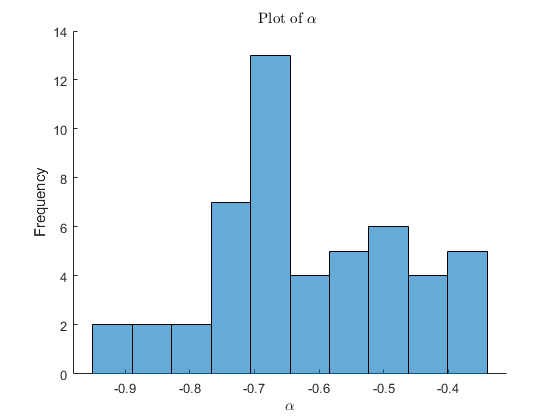


figure(1)
hold on
histogram(ols2_mat(:,3),bins)
xlabel('$\alpha$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\alpha$ ','interpreter','LaTex')
hold off

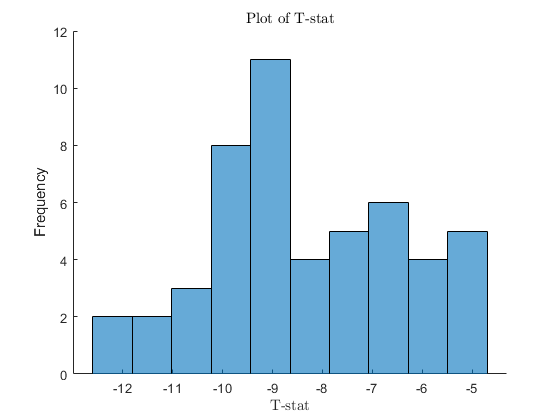


figure(2)
hold on
histogram(t_stat_alpha,bins)
xlabel('T-stat','interpreter','LaTex'); ylabel('Frequency')
title('Plot of T-stat','interpreter','LaTex')
hold off

## **Plot the estimated coefficients and distribution of t-stats from all simulations **$\alpha$ = 0.1

bins = 10;

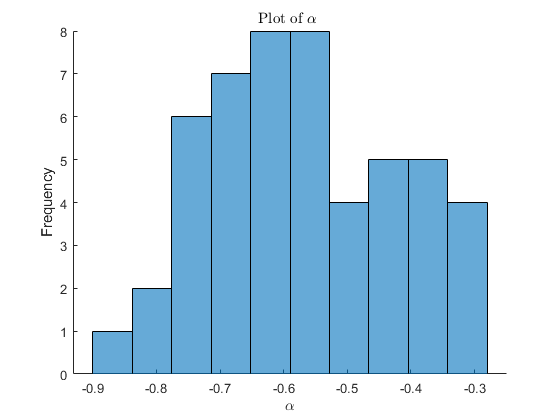


figure(10)
hold on
histogram(ols2_mat(:,3),bins)
xlabel('$\alpha$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\alpha$ ','interpreter','LaTex')
hold off

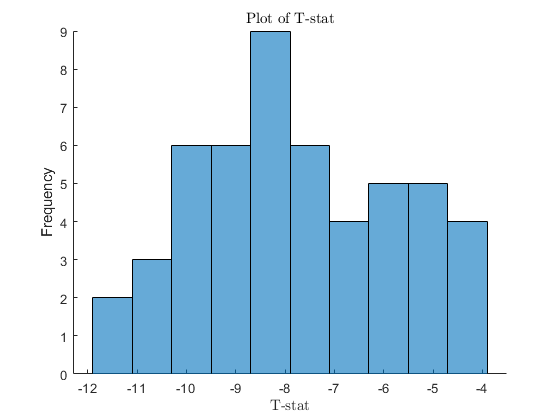


figure(11)
hold on
histogram(t_stat_alpha,bins)
xlabel('T-stat','interpreter','LaTex'); ylabel('Frequency')
title('Plot of T-stat','interpreter','LaTex')
hold off

## Question 2. ii)

ii) Regress $y_t$ on $x_t$ and also regress $\Delta y_t$ on $\Delta x_t$ . In either case, the coefficient is $\alpha$. Do this for T = 50 and for T = 500. Can you see the super-consistency kick in? (Print the mean, variance, and skewness, and a frequency plot would also be nice)

## Set the parameters.

There are 50 simulations with 500 observations per simulation. 

clc
clear
clf

global y T

T = 500;                             % Number of time periods.
mu = 0;                           % Mu.
alpha =1;                       % Alpha.
sigma = 1;                         % Standard deviation.

sim = 50;                             % Number of simulations.
                                  
ols_matii = zeros(sim,3);                                      % OLS matrix.


## **OLS Estimation**


for s = 1:sim
    
    % Draw error terms.
    
    e = normrnd(0,2,T,1); %innovations for y
    
    u = normrnd(0,3,T,1); %innovations for x
    
    y = zeros(T,1);
    x = zeros(T,1);
    for i=2:T
        x(i,:) = x(i-1) + u(i,:);
        y(i,:) = alpha*x(i,:) + e(i,:);
    end
   
    % OLS. Regress x on y
    
    X = [ones(T-1,1) x(1:T-1)];
    Y = y(1:T-1);    
    b_ols = (X'*X)\X'*Y;
        
    u_ols  = Y - X*b_ols;
    s2_ols = u_ols'*u_ols/(T-size(X,2));
    
    
    ols2ii_mat(s,1:2) = b_ols';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    v_olsii  = s2_ols*inv(X'*X);
    
    
    % OLS. Regress Delta x on delta y
    delta_y = y(2:T-1,:)- y(1:T-2,:);
    delta_x = x(2:T-1,:)- x(1:T-2,:);
    
    intercept = ones(T-2,1);
    X1 = [intercept delta_x];
    Y1 = delta_y;    
    b_ols1 = (X1'*X1)\X1'*Y1;
        
    u_ols1  = Y - X*b_ols1;
    s2_ols1 = u_ols1'*u_ols1/(T-size(X1,2));
    
    ols2ii_mat1(s,1:2) = b_ols1';
    %ols2_mat(s,length(b_ols)) = sqrt(s2_ols);
    v_olsii_1  = s2_ols1*inv(X1'*X1);
    
end

Saving Levels Regression Results


t_stats = (ols2ii_mat)./(sqrt(diag(v_olsii))');
t_stat_alpha = t_stats(:,2);
beta_mean = mean(ols2ii_mat(:,2));
var_b_ols = v_olsii(2,2);
skew = skewness(ols2ii_mat(:,2))

skew = 0.2634

Saving 1st Difference Regression Results

t_stats1 = (ols2ii_mat1)./(sqrt(diag(v_olsii_1))');
t_stat_alpha1 = t_stats(:,2);
beta_mean1 = mean(ols2ii_mat1(:,2));
var_b_ols1 = v_olsii_1(2,2);
skew1 = skewness(ols2ii_mat1(:,2))

skew1 = 0.0752

## Empirical results.

The mean, variance, and skewness of $\hat{\beta$ estimated using OLS in levels:

fprintf(' %0.4f\n %0.4f\n %0.4f\n', beta_mean, var_b_ols, skew)

 0.9996
 0.0000
 0.2634


The mean, variance, and skewness of $\hat{\beta$ estimated using OLS in first differences:

fprintf(' %0.4f\n %0.4f\n %0.4f\n', beta_mean1, var_b_ols1, skew1)

 0.9949
 0.0012
 0.0752


**Plot of estimated **$\hat{\alpha}$**, by OLS in levels.**

**T=50**

bins = 10;


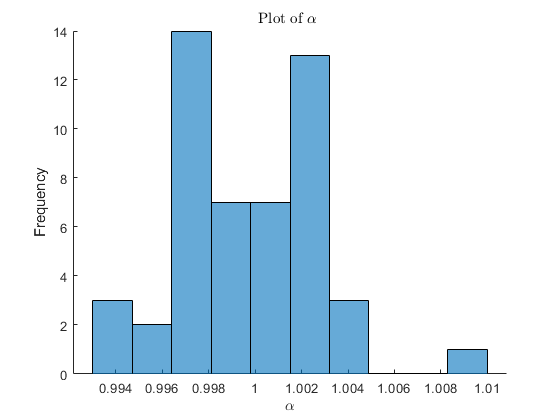

figure(3)
hold on
histogram(ols2ii_mat(:,2),bins)
xlabel('$\alpha$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\alpha$ ','interpreter','LaTex')
hold off

**Plot of estimated **$\hat{\alpha}$**, by OLS in first differences.**

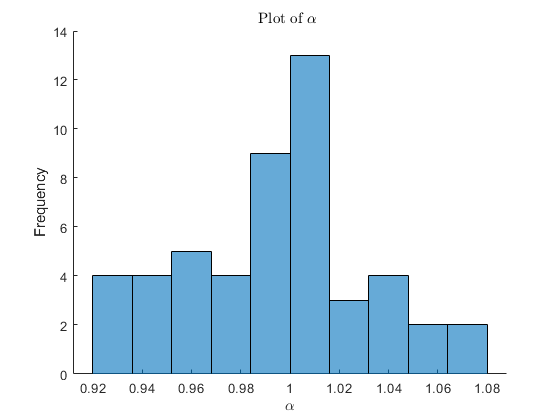


figure(4)
hold on
histogram(ols2ii_mat1(:,2),bins)
xlabel('$\alpha$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\alpha$ ','interpreter','LaTex')
hold off

## Plots when T=500

bins = 10;

**Plot of estimated **$\hat{\alpha}$**, by OLS in levels.**

figure(5)
hold on
histogram(ols2ii_mat(:,2),bins)
xlabel('$\alpha$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\alpha$ ','interpreter','LaTex')
hold off

**Plot of estimated **$\hat{\alpha}$**, by OLS in first differences.**

figure(6)
hold on
histogram(ols2ii_mat1(:,2),bins)
xlabel('$\alpha$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\alpha$ ','interpreter','LaTex')
hold off